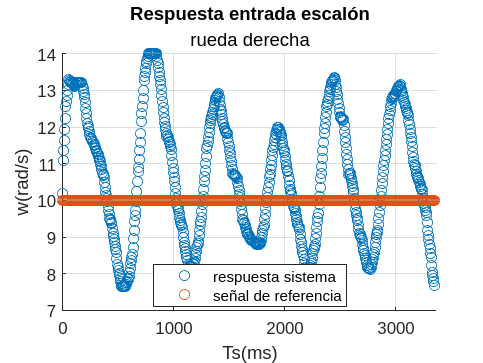

clear all
close all
%read data example: Import columns as column vectors 
A=readmatrix("prueba.csv");
t=A(:,1);
referencia=A(:,2);
WD=A(:,3);
WI=A(:,4);
figure(1)
scatter(t(1:3360/5),WD(1:3360/5))
hold on
scatter(t(1:3360/5),referencia(1:3360/5))
grid on
xlim([0 3370])
title("Respuesta entrada escalón")
subtitle("rueda derecha")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')

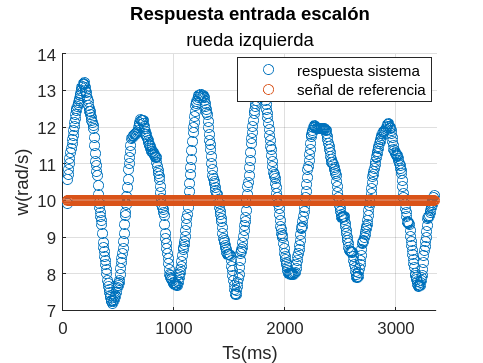

figure(2)
scatter(t(10:3360/5),WI(10:3360/5))
hold on
scatter(t(10:3360/5),referencia(10:3360/5))
grid on
xlim([0 3370])
title("Respuesta entrada escalón")
subtitle("rueda izquierda")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')

%Tunning rueda derecha
kc=2

kc = 2

Tc=(3040-2450)*10^-3

Tc = 0.5900


%P
kp1=0.5*kc

kp1 = 1

%PI
kp2=0.4*kc

kp2 = 0.8000

ki2=0.8*Tc

ki2 = 0.4720

%PID
kp3=0.6*kc

kp3 = 1.2000

ki3=0.5*Tc

ki3 = 0.2950

kd3=0.125*Tc

kd3 = 0.0738

%Tunning rueda izquierda
kc=2

kc = 2

Tc=(1800-1250)*10^-3

Tc = 0.5500

%P
kp1=0.5*kc

kp1 = 1

%PI
kp2=0.4*kc

kp2 = 0.8000

ki2=0.8*Tc

ki2 = 0.4400

%PID
kp3=0.6*kc

kp3 = 1.2000

ki3=0.5*Tc

ki3 = 0.2750

kd3=0.125*Tc

kd3 = 0.0688

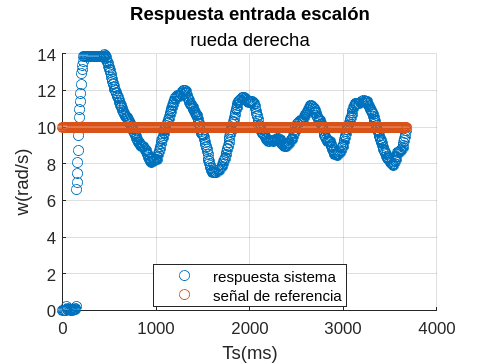

close all 
clear all
%read data example: Import columns as column vectors 
A=readmatrix("parametrosZ-N.csv");
t=A(:,1);
referencia=A(:,2);
WD=A(:,3);
WI=A(:,4);

figure(1)
scatter(t,WD)
hold on
scatter(t,referencia)
grid on
title("Respuesta entrada escalón")
subtitle("rueda derecha")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')

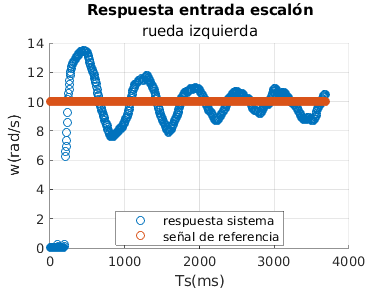

figure(2)
scatter(t,WI)
hold on
scatter(t,referencia)
grid on
title("Respuesta entrada escalón")
subtitle("rueda izquierda")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')

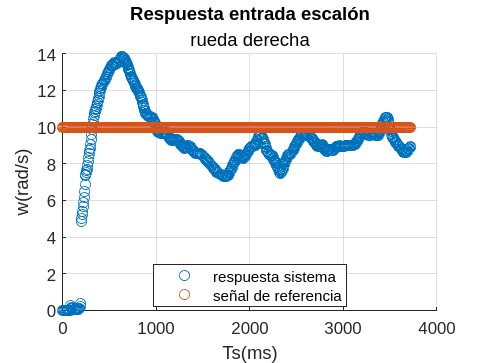

close all 
clear all
%read data example: Import columns as column vectors 
A=readmatrix("opti.csv");
t=A(:,1);
referencia=A(:,2);
WD=A(:,4);
WI=A(:,5);

figure(1)
scatter(t,WD)
hold on
scatter(t,referencia)
grid on
title("Respuesta entrada escalón")
subtitle("rueda derecha")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')

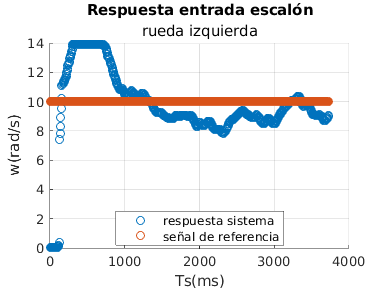

figure(2)
scatter(t,WI)
hold on
scatter(t,referencia)
grid on
title("Respuesta entrada escalón")
subtitle("rueda izquierda")
xlabel("Ts(ms)")
ylabel("w(rad/s)")
legend("respuesta sistema","señal de referencia",'location','best')